Matlab live script example + basic stuff

Example of circle area calculation:

r = 2;
format long
area = pi*r^2

area =   12.566370614359172


format short
disp("short format:")

short format:


disp(area)

   12.5664



Basic arrays

x = [3, 2, 1]

x =      3     2     1


x(1)

ans = 3

y = 1:0.5:10

y =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


z = 10:-1:1

z =     10     9     8     7     6     5     4     3     2     1


y_first_5 = y(1:5)

y_first_5 =     1.0000    1.5000    2.0000    2.5000    3.0000


y_last_5 = y(end-4:end)

y_last_5 =     8.0000    8.5000    9.0000    9.5000   10.0000


y_even_pos = y(2:2:end)

y_even_pos =     1.5000    2.5000    3.5000    4.5000    5.5000    6.5000    7.5000    8.5000    9.5000


y_rand_pos = y([5, 2, 8, 1, 3])

y_rand_pos =     3.0000    1.5000    4.5000    1.0000    2.0000


y_greater_then_5 = y( y > 5)

y_greater_then_5 =     5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


tmp = y > 5

tmp = 1×19 logical array
   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1


t = 0:0.1:10;
z = sin(t);
t_pos_sin = t(z > 0)

t_pos_sin =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000    8.1000


[~, z_max_ind] = max(z)

z_max_ind = 17

size(z)

ans =      1   101


length(z)

ans = 101

col = [1; 2; 3]

col =      1
     2
     3


col_x = x'

col_x =      3
     2
     1


x*col

ans = 10

x.*col'

ans =      3     4     3


x.*col

ans =      3     2     1
     6     4     2
     9     6     3


% x*col' % error
x*2

ans =      6     4     2


x

x =      3     2     1


x_copy = x

x_copy =      3     2     1


x(2) = 5

x =      3     5     1


x_copy

x_copy =      3     2     1


y(1:5) = 1:5

y =     1.0000    2.0000    3.0000    4.0000    5.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


2D-arrays (matrices)


A = [1, 2, 3; 4, 5, 6; 7, 8, 9]

A =      1     2     3
     4     5     6
     7     8     9


A(2,2)

ans = 5

A(:,end)

ans =      3
     6
     9


A(1:2,1:2)

ans =      1     2
     4     5


Z = zeros(3,5)

Z =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


O = ones(1,3)

O =      1     1     1


E = eye(5)

E =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


R = rand(4,5)

R =     0.4324    0.7637    0.5178    0.6789    0.2318
    0.7492    0.5588    0.9942    0.4035    0.3963
    0.0392    0.1838    0.8549    0.9350    0.7051
    0.9463    0.4979    0.9624    0.4795    0.5586


Ri = randi([-4,4],[2,3])

Ri =      2     4     4
     4     0    -3


Plotting

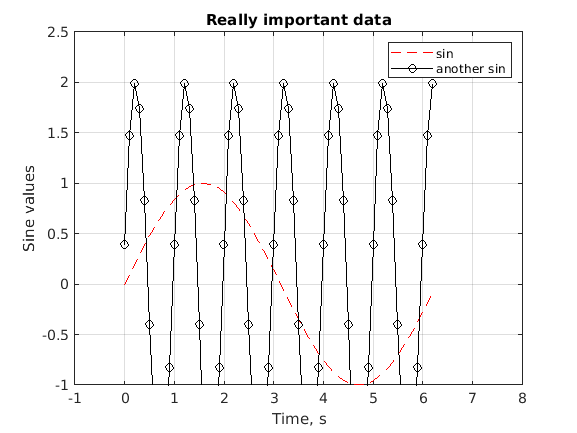

t = 0:0.1:2*pi;
y = sin(t);
z = 2*sin(2*pi*t + 0.2);
plot(t,y,'r--');
grid on;
hold on;
plot(t,z,'ko-');
legend("sin","another sin");
axis([-1, 8, -1, 2.5])
title('Really important data');
xlabel('Time, s');
ylabel('Sine values');
hold off;

Basic code constructions

val = 1;
if val ~= 2
    disp("Greater");
else
    disp("Less");
end

Greater



for idx=1:10
    disp(idx)
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10




val = 16

val = 16

while (val > 1)
    val = val/2;
    % val /= 2
end
disp(val);

     1



A = [1 1; 
    1 -1];
b = [2;0];
x = inv(A)*b

x =      1
     1


x = A\b

x =      1
     1
